# Subset analysis

**Author**: Scott Campit

## Summary

## Tissue analysis

gcp = readtable('~/Data/Expression/Proteomics/GCP/GCP_single.csv');
map = gcp(:, 1:4);
data = gcp(:, 5:end);

## Bar plot of the number of samples for each tissue lineage in the CCLE

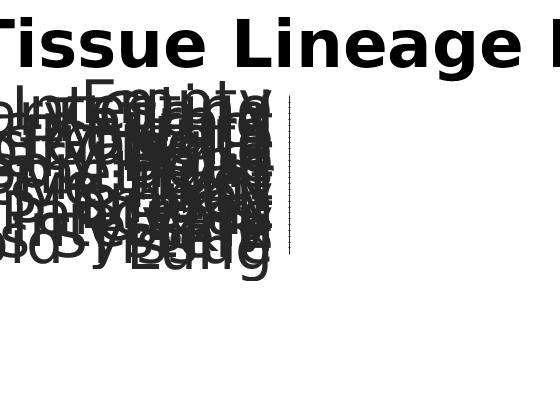

unqTissue = unique(map.Lineage);
for i = 1:length(unqTissue)
    tissueCounts(i) = sum(count(map.Lineage, string(unqTissue(i))));
end
[sortedCounts, idx] = sort(tissueCounts);
unqTissue = categorical(unqTissue);
unqTissue = unqTissue(idx);

% Construct the bar plot
figure();
barh(sortedCounts);
set(gca, ...
    'YTickLabels', unqTissue, ...
    'YTick', 1:length(unqTissue), ...
    'YDir','reverse', ...
    'FontSize', 45);
xlabel('Counts'); ylabel('Tissue lineages');
title('CCLE GCP Tissue Lineage Distribution');
xline(20);

## Boxplot of the number of samples for each tissue lineage in the CCLE

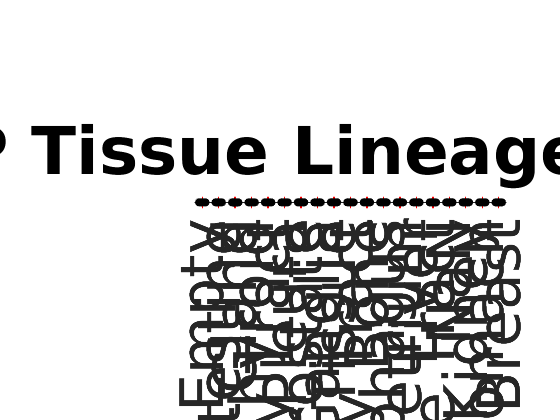

data2 = table2array(data);

% Construct the bar plot
figure();

% Create boxplot
%boxplot(data2, ...
%    'Notch', 'on', 'Colors', 'r', ...
%    'OutlierSize', 8, 'jitter', 0.05)
%hold on;

% Create matrix for categorical scatterplot
for k = 1:size(data2, 2)
    tmp(:, k) = ones(size(data2, 1), 1) .* k;
end

% Create categorical scatterplot
for j = 1:size(data2, 2)
    scatter(tmp(:, j), data2(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.7, ...
        'jitter', 0.05)
end

set(gca, ...
    'XTickLabels', unqTissue, ...
    'XTick', 1:length(unqTissue), ...
    'FontSize', 45);
xlabel('Tissue lineages'); ylabel('Z-score');
title('CCLE GCP Tissue Lineage Distribution');
xtickangle(90);